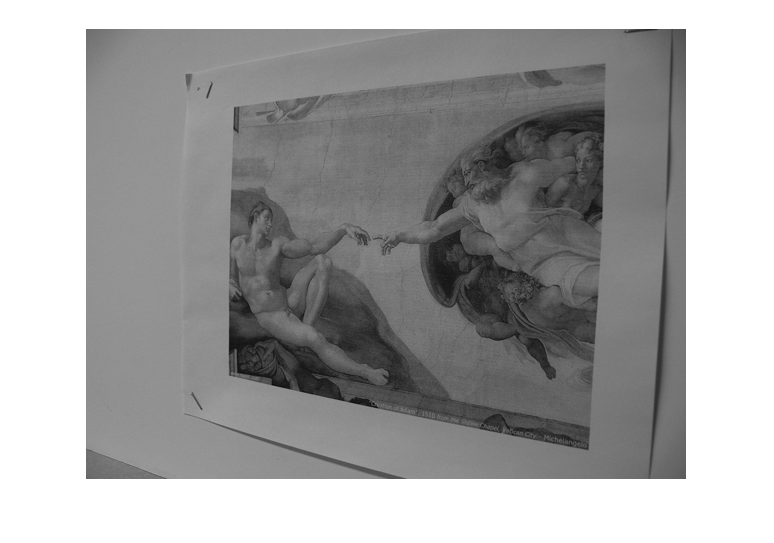

imgA=rgb2gray(imread('adamA.png'));
kpA=detectSURFFeatures(imgA);
%theta=30/180*pi;
%H1=[cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1];
%tform = projective2d(H1);
%imgB=imwarp(imgA,tform);
imgB=rgb2gray(imread('adamB.png'));
figure,imshow(imgB)

kpB=detectSURFFeatures(imgB);

[featuresA, valid_pointsA] = extractFeatures(imgA, kpA,  'Method' ,'SURF');
[featuresB, valid_pointsB] = extractFeatures(imgB, kpB,  'Method' ,'SURF');
 indexPairs=matchFeatures(featuresA,featuresB);
 matchedPoints1=valid_pointsA(indexPairs(:,1),:);
 matchedPoints2=valid_pointsB(indexPairs(:,2),:);
 %%
 M=zeros(length(indexPairs),10);
 M(:,1:2)=matchedPoints1.Location;
 M(:,3)=1;
 M(:,4:5)=matchedPoints2.Location;
 M(:,6)=1;
 M(:,7)=matchedPoints1.Scale;
 M(:,8)=matchedPoints2.Scale;
 M(:,9)=matchedPoints1.Orientation;
 M(:,10)=matchedPoints2.Orientation;
 
 